# Figure 4: S_EE and S_II

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];
Panel1 = length(S_EEtest); Panel2 = length(S_IItest);
S_ElgnInd = 3;
S_IlgnInd = 2; % $(seq 2 4)
rI_L6Ind = 3;  % 3 6

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

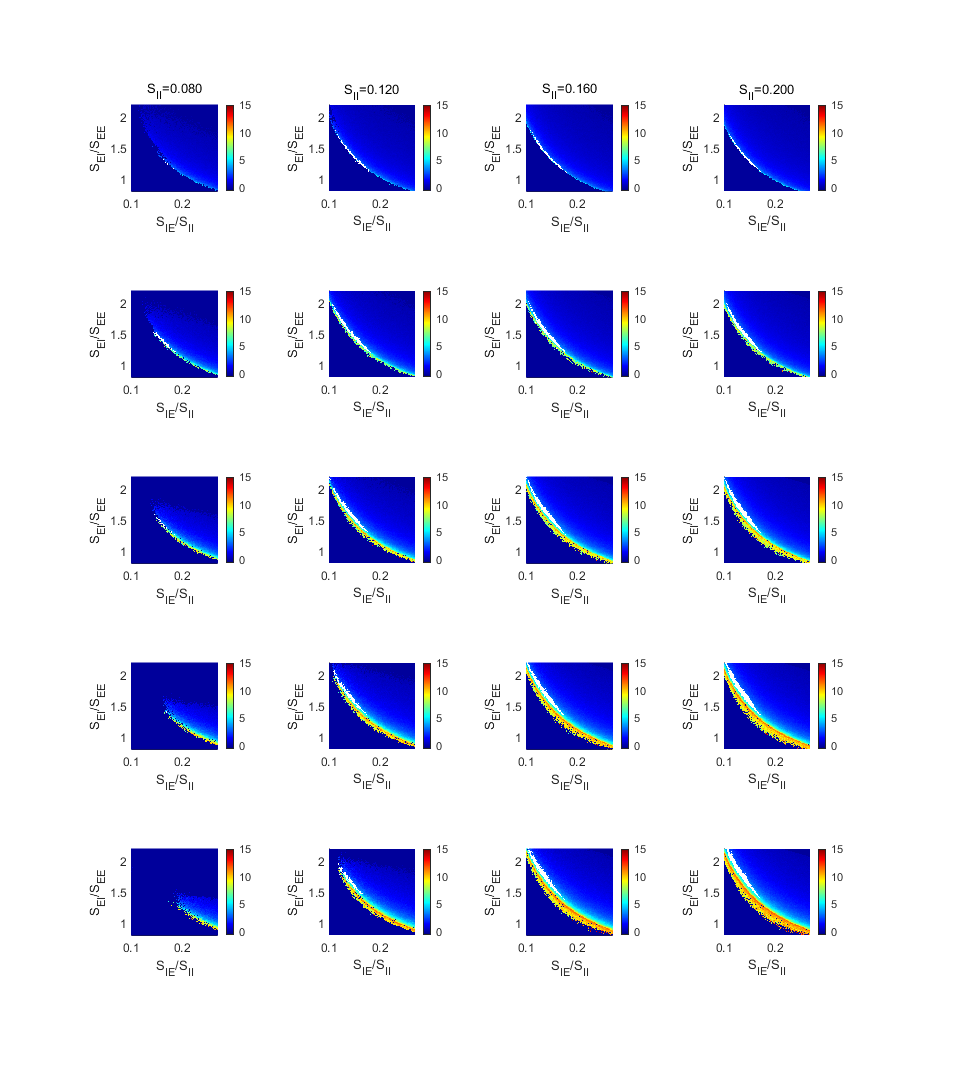

Fig1 = figure('Name','SEE_SII','units','normalized','outerposition',[0 0 0.67 1]);
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('FigContour_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContour_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
%         [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
%             CurrentFrE,[3  5 ],'ShowText','on','color','r');
%         clabel(C1,h1,'FontSize',10,'Color','k')
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 15])
        hold off
%         title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
%                        S_EE,        S_II,        S_Elgn,        S_Ilgn))
        if S_EEInd == 1
            title(sprintf('S_{II}=%.3f',S_II)) 
        end
        if S_IIInd == 1
            ylabel({sprintf('S_{EE}=%.3f',S_EE),'','S_{EI}/S_{EE}'})
        end
        xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
        axis square
    end
end

Save figures

% MF_7Dpath = [FigurePath '\MF_7D_fine\'];
% FigName1 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rE',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% FigName2 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rRatio',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% savefig(Fig1,[MF_7Dpath FigName1 '.fig']);
% savefig(Fig2,[MF_7Dpath FigName2 '.fig']);

Print Figs

% Fig1.PaperUnits = 'centimeters';
% Fig1.PaperSize = [41.95,25.68];
% Fig1.PaperOrientation = "landscape";
% exportgraphics(Fig1,[MF_7Dpath FigName1 '.pdf'],'Resolution',600)
% exportgraphics(Fig2,[MF_7Dpath FigName2 '.pdf'],'Resolution',600)